% Quality control and Time Series analysis
%loading the Data
BUOY_44009_WT = readtable('buoy 44009 water temp.csv', VariableNamingRule='preserve');
BUOY_Lewes_WT = readtable('LWSD1_WT', VariableNamingRule='preserve');
Date = readtable('Datetime_hourly_wt.csv', VariableNamingRule='preserve');
WAVEGLIDER_WT = readtable('WG ADCP C2T Esemble', VariableNamingRule='preserve');
AWAC = readtable('OTS_20221115_202033_20221130_132033_AWAC-WPB', VariableNamingRule='preserve');
EOLOS = readtable("E:\Verification_Data\Eolamiri\BuoyE14_Hourly-20240322T132538Z-001\BuoyE14_Hourly\Combined\EOLOSFiltered.csv", VariableNamingRule='preserve');

%DECARING THE VARIABLES COLUMNS FOR EACH STATION
%WaveGlider data
WGwt = WAVEGLIDER_WT{:,5}; Buoy_WT = BUOY_44009_WT{:,7}; Lewes_WT = BUOY_Lewes_WT{:,7};


WGwt(WGwt == 9999 | WGwt == 999) = NaN;
Buoy_WT(Buoy_WT == 9999 | Buoy_WT == 999) = NaN;
Lewes_WT(Lewes_WT == 9999 | Lewes_WT == 999) = NaN;


%CHANGE FOR STATION KEEPING OR RACETRACK
range = 1:193;
%X axis 1:193 (racetrack) and  193:312 (Station Keeping)
Dateti = WAVEGLIDER{:,1};
Datetimm = Dateti(1:6:length(Dateti));
Datetim = (Datetimm(range, :));

%Averaging all data from mins to hourly
BuoyWT_hourly = tenmins_to_hourly(Buoy_WT);
WGwt_hourly = thirtymins_to_hourly(WGwt);
LewesWT_hourly = six_to_hourly(Lewes_WT);

data_grid2 = WGwt_hourly;

%CREATING A GRID (When the difference is less than 1
% wtt=find(pressure_diff < 1 | pressure_diff > -1);
% data_grid2(wtt)=NaN;

wgwt_h =(WGwt_hourly); bwt_h =(BuoyWT_hourly);Lwt_h =(LewesWT_hourly);



figure
plot(Datetim, bwt_h(range,:),'.', color = 'red')
hold on
plot(Datetim, wgwt_h(range,:),'--o',Color='k')
hold on
% plot(Datetim, Lwt_h(range,:),'-*','color','b',LineWidth=0.8)
% hold on
% plot(Datetim, EOLOS{:,3},'.','color','b',LineWidth=1.2)
% hold on
% plot(Datetim, AWAC{:,8},'-*','color','magenta',LineWidth=0.8)
hold off
% plot(Datetim, data_grid2,'-',LineWidth=2)
% hold off
xlim tight
% xline(8.9,'--',{'Start'},LineWidth=1.5);
% xline(13,'--',{'End'},LineWidth=1.5);
legend('Buoy 44009','Waveglider','LWSD1',location='best')

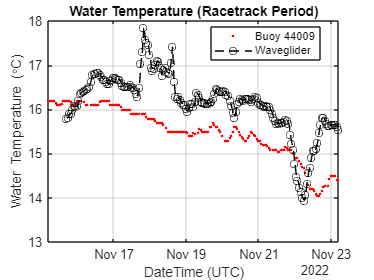

title('Water Temperature (Racetrack Period)')
xlabel('DateTime (UTC)');
ylabel('Water Temperature (\circC)');

% xticks([Datetim(1:24:352)])
% xtickformat('dd')

grid on

% ax = gca;
% ax.XAxis.MinorTick = 'on';
% ax.XAxis.MinorTickValues = Datetim;


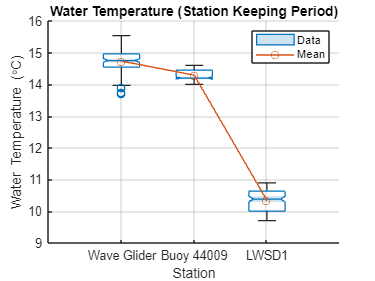

% BOX and Whisker Plots
%CHANGE FOR STATION KEEPING OR RACETRACK
range = 193:312;
%X axis 1:193 (racetrack) and  193:312 (Station Keeping)

Lwt_h = Lwt_h(range,:);
wgwt_h = wgwt_h(range, :);
bwt_h = bwt_h(range, :);
% wgwt_h = filloutliers(wgwt_h, NaN, 'mean');
% bwt_h = filloutliers(bwt_h, NaN, 'mean');
% Lwt_h = filloutliers(Lwt_h, NaN, 'mean');


% Calculate the mean of each array, ignoring NaN values
mean_wgwt_h = nanmean(wgwt_h);
mean_bwt_h = nanmean(bwt_h);
mean_Lwt_h = nanmean(Lwt_h);

% Combine the means into a single matrix
meanWeight1 = [mean_wgwt_h; mean_bwt_h; mean_Lwt_h];
% meanWeight1 = (mean([wgsm_h(range, :), bsm_h(range, :), DsmR_h(range, :),DsmI_h(range, :),Csm_h(range, :),Lsm_h(range, :)]));
figure
boxchart([wgwt_h, bwt_h, Lwt_h],'Notch', 'on')
hold on
plot(meanWeight1,'-o')
hold off
ylabel('Water Temperature (\circC)');
xlabel('Station');
title('Water Temperature (Station Keeping Period)')
xticklabels({'Wave Glider','Buoy 44009','LWSD1'})
legend(["Data","Mean"])
grid on